% Judge whether a watermelon is good by its density and sugar content
% Based on LDA method
% The purpose is to find the best projection direction omega

首先，根据课本89页表4.5给出的西瓜数据集3.0α，将信息录入程序中。

% We use the data given as DATASET_3.0alpha on page 89
% Firstly, get all dadta
% There are 17 records in total, and each row represents a watermelon
% The data of each watermelon is in form:
% [number of the watermelon, density, sugar content, good(1) or bad(0)]
watermelons = [1 0.697 0.460 1;
               2 0.774 0.376 1;
               3 0.634 0.264 1;
               4 0.608 0.318 1;
               5 0.556 0.215 1;
               6 0.403 0.237 1;
               7 0.481 0.149 1;
               8 0.437 0.211 1;
               9 0.666 0.091 0;
               10 0.243 0.267 0;
               11 0.245 0.057 0;
               12 0.343 0.099 0;
               13 0.639 0.161 0;
               14 0.657 0.198 0;
               15 0.360 0.370 0;
               16 0.593 0.042 0;
               17 0.719 0.103 0];

检查无误后，录入的数据如下。

`watermelons = ``17×4`    ` 行 7:16 | 列 1:4`

`    1.0000    0.6970    0.4600    1.0000`

`    2.0000    0.7740    0.3760    1.0000`

`    3.0000    0.6340    0.2640    1.0000`

`    4.0000    0.6080    0.3180    1.0000`

`    5.0000    0.5560    0.2150    1.0000`

`    6.0000    0.4030    0.2370    1.0000`

`    7.0000    0.4810    0.1490    1.0000`

`    8.0000    0.4370    0.2110    1.0000`

`    9.0000    0.6660    0.0910         0`

`   10.0000    0.2430    0.2670         0`

`   11.0000    0.2450    0.0570         0`

`   12.0000    0.3430    0.0990         0`

`   13.0000    0.6390    0.1610         0`

`   14.0000    0.6570    0.1980         0`

`   15.0000    0.3600    0.3700         0`

`   16.0000    0.5930    0.0420         0`

`   17.0000    0.7190    0.1030         0`

`然后在数据集中，将好瓜和坏瓜分开，分别构成两个数据集合。`

% Get good ones and bad ones in the dataset
good_watermelons = [];
bad_watermelons = [];
for i = 1:1:17
    if watermelons(i,4) == 1
        good_watermelons = [good_watermelons; watermelons(i,1:end)];
    else
        bad_watermelons = [bad_watermelons; watermelons(i,1:end)];
    end
end

% test
% good_watermelons
% bad_watermelons

在录入数据时，好瓜的特征为1，坏瓜的特征为0，据此分类得到的两数据集合如下。

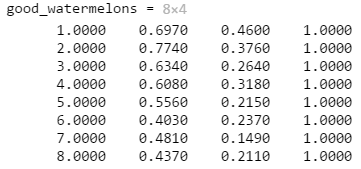

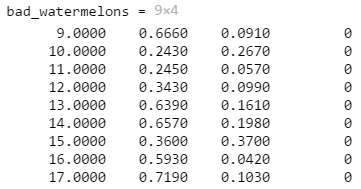

检查无误，下面进行后续处理。

由LDA方法，先分别计算两类数据各自的中心。用miu_0表示坏瓜的中心，miu_1表示好瓜的中心，得到的结果如下。

 

% Calculate the certer of each class

% The certer of good watermelons in coloum vector form
% miu_1 is the center of good watermelons
% miu_0 is the center of bad watermelons
miu_1 = [mean(good_watermelons(1:end,2)), mean(good_watermelons(1:end,3))]';
miu_0 = [mean(bad_watermelons(1:end,2)), mean(bad_watermelons(1:end,3))]';

% test
% miu_0
% miu_1

接下来，根据所有数据和两类数据的中心，计算类间散度矩阵Sb和类内散度矩阵Sw。

% Calculate the between-class sactter matrix Sb
Sb = (miu_0-miu_1)*(miu_0-miu_1)';

% test
% Sb

% Calculate the within_class scatter matrix

% The shape of Sw is decided by the numbers of properties given in the dataset
Sw = zeros(2,2); 

for i = 1:1:size(good_watermelons,1)
    Sw = Sw+(good_watermelons(i,2:3)'-miu_1)*(good_watermelons(i,2:3)'-miu_1)';
end
for i = 1:1:size(bad_watermelons,1)
    Sw = Sw+(bad_watermelons(i,2:3)'-miu_0)*(bad_watermelons(i,2:3)'-miu_0)';
end

% test
% Sw

得到的类间散度矩阵Sb为：

得到的类内散度矩阵Sw为：

使用LDA方法将数据进行投影，需要计算投影方向，而投影方向的计算需要使用到Sw的逆矩阵。该逆矩阵可以直接求，但为了保证数值解的稳定性，使用奇异值分解的方法更好。下面对Sw进行奇异值分解，并利用对角阵、正交阵的性质求取Sw的逆矩阵。

% Do Singular Value Decomposition(SVD) for Sw and calculate the inverse of Sw
[U,S,V] = svd(Sw);
Sw_inverse = V*S^(-1)*U';

% test
% Sw_inverse

得到Sw的逆矩阵如下。事实上，可以检验，得到的结果和直接使用Sw^(-1)得到的结果是一致的。

这样，根据LDA方法的理论分析，就可以计算出所用的投影方向。在计算过程中发现，得到的投影方向的方向向量两个分量都为负，且模长不为1。事实上，由于本问题只有两维，这里的w表示了一条直线，所有的数据投影到这条直线上。为了后续能够方便地计算投影后数据点坐标，在得到原始的w后，将保持其方向不变，将其模长规范化为1。

此外，为了符合个人的习惯，将w的两个分量都取反，相当于将方向向量反向，所表示的投影直线不变，不改变后续的计算结果。

% Calculate the projection direction 
w = Sw_inverse*(miu_0-miu_1);
display('The projection direction vector is:');
display(w);

% The norm of w might not be 1, so we need to normlize it
norm_w = norm(w);
w = 1/norm_w*w;
display('The normalized projection direction vector is:');
display(w);

w = -1*w; % In later process we find w is double negetive, so reverse it
% do not effect the projection direction
% but make calculate more convenient
display('The normalized and reversed projection direction vector is:');
display(w);

% test
% w
% norm(w)

得到的初始的、规范化后的、反向并规范化后的投影方向向量分别如下。

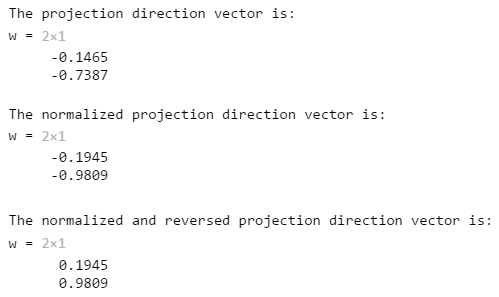

至此就已经完成了LDA方法。当得到一个新的数据需要预测时，将该数据投影到求得的方向上，设计一定规则计算投影点与两类别投影点的位置关系，例如与各自中心投影点的距离，就可以进行分类预测了。

下面对本问题求得的结果进行简单分析。

首先将数据集中的点在坐标系中表示出来，将密度作为x轴，含糖量作为y轴（这是因为在前面的所有计算过程中，都将密度作为了第一分量，含糖量作为了第二分量），数据散点图如下。

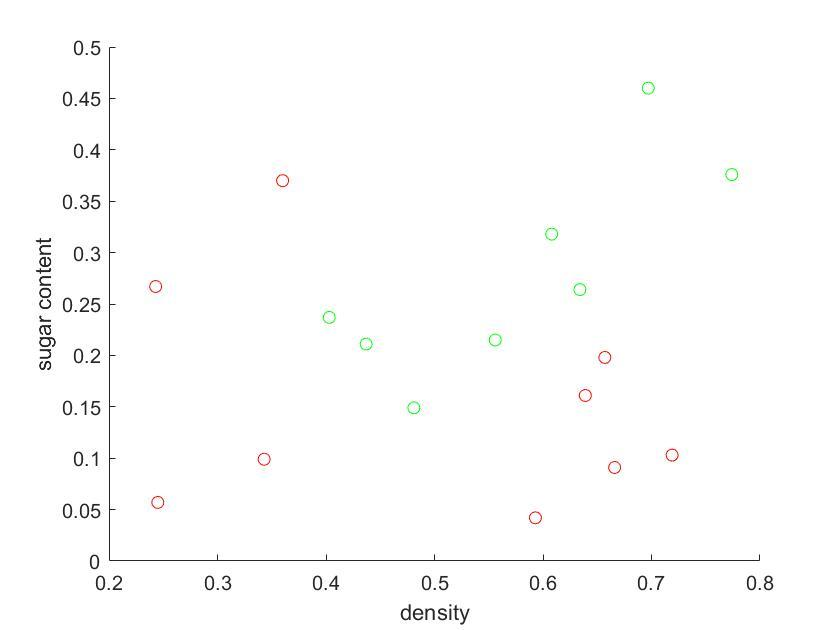

% The next is to make the results visionable
% Let desity be the first axis(x), and sugar content the second(y)
hold on;
xlabel('density');
ylabel('sugar content');

% Show bad watermelons and good watermelons
plot(bad_watermelons(1:end,2), bad_watermelons(1:end,3), 'ro');
plot(good_watermelons(1:end,2), good_watermelons(1:end,3), 'go');

画出之前得到的投影方向向量所表示的直线，然后将各数据点的投影点坐标计算出来并标出。此外，再将两类别的中心点投影在直线上并标出。得到的结果如下图，投影直线上的两圆圈分别表示两类别的中心点的投影。

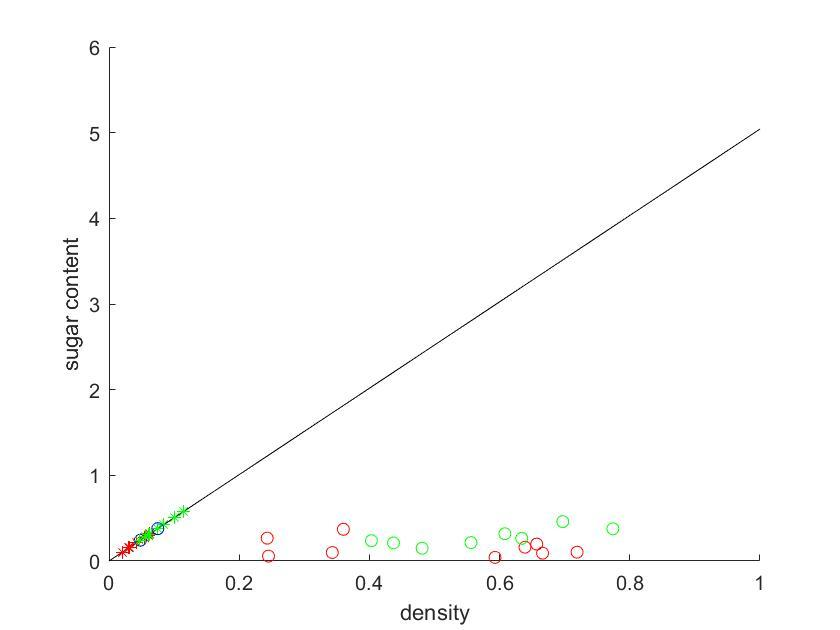

需要说明的是，从投影点坐标的计算方法中可以看出，之前将w向量反向并不是必须的。计算投影后坐标的思路是，利用向量的点积以及方向向量模长为1的特性，得到投影后的有向长度，然后再将方向向量根据有向长度进心缩放得到投影点坐标。如果不对w进行反向，那么w的两分量都为负，但于此同时，各数据点投影后的有向长度也将取相反数，所以最终的结果不会改变。

此外，上图的横纵两坐标轴尺度不同，因此投影操作直观上并不是垂直投影，改变坐标尺度一致即可得到正常的投影效果，如下图。

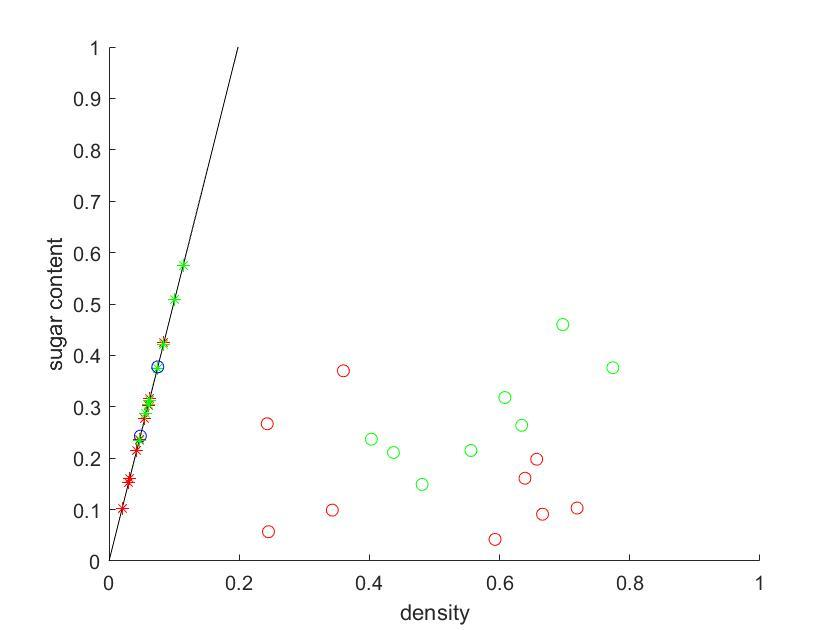

% Show projection direction
x = 0:0.01:1;
y = x/w(1)*w(2);
plot(x,y,'k-');

% process bad watermelons
bad_projection_length = w'*bad_watermelons(1:end,2:3)';
bad_projection_points = [w(1)*bad_projection_length;w(2)*bad_projection_length];
plot(bad_projection_points(1,1:end),bad_projection_points(2,1:end),'r*');
bad_projection_center = w'*miu_0*w;
plot(bad_projection_center(1),bad_projection_center(2),'bo');

% process good watermelons
good_projection_length = w'*good_watermelons(1:end,2:3)';
good_projection_points = [w(1)*good_projection_length;w(2)*good_projection_length];
plot(good_projection_points(1,1:end),good_projection_points(2,1:end),'g*');
good_projection_center = w'*miu_1*w;
plot(good_projection_center(1),good_projection_center(2),'bo');

hold off;

上图因为包含了原始数据点，所以在投影直线上的情况并不是很清楚，将投影直线单独绘制为一张图，得到的结果如下。

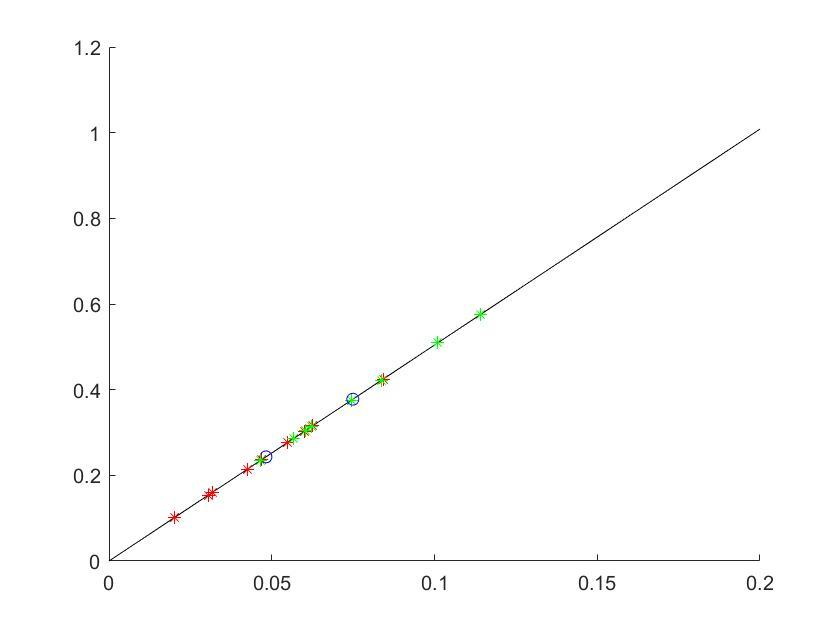

直观上能够很清楚地看到，两类数据点在投影后有较大的区分，类内的投影点相互靠近，类间的投影点相距较大，形成了两个明显的聚类，两类别的中心点投影相距较远。两类别的投影点有一定重叠，这是因为两类别原始的数据就有一定的重叠交叉，如果用分类角度来看的话，这是一个类似于“异或”的问题，从之前的图中可以看出，没有办法用一条直线对原始数据进行很好的分类。总的来说，LDA方法得到的结果还是不错的，达到了通过投影进行较为显著分类的目的。